Membuka Citra

clear all;
I=imread('2.jpg');
figure,
imshow(I);

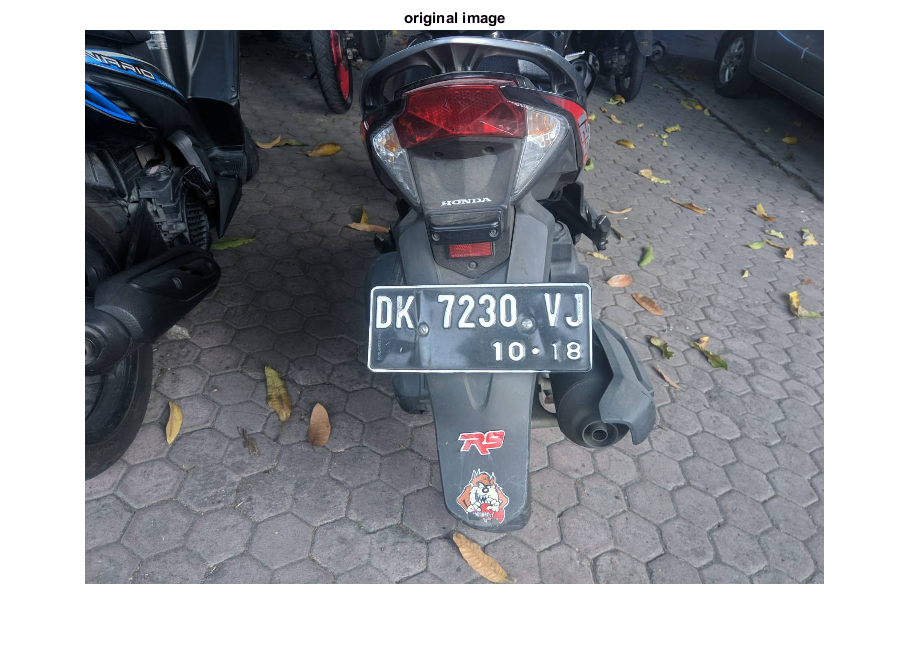

title('original image');

Convert Grayscale

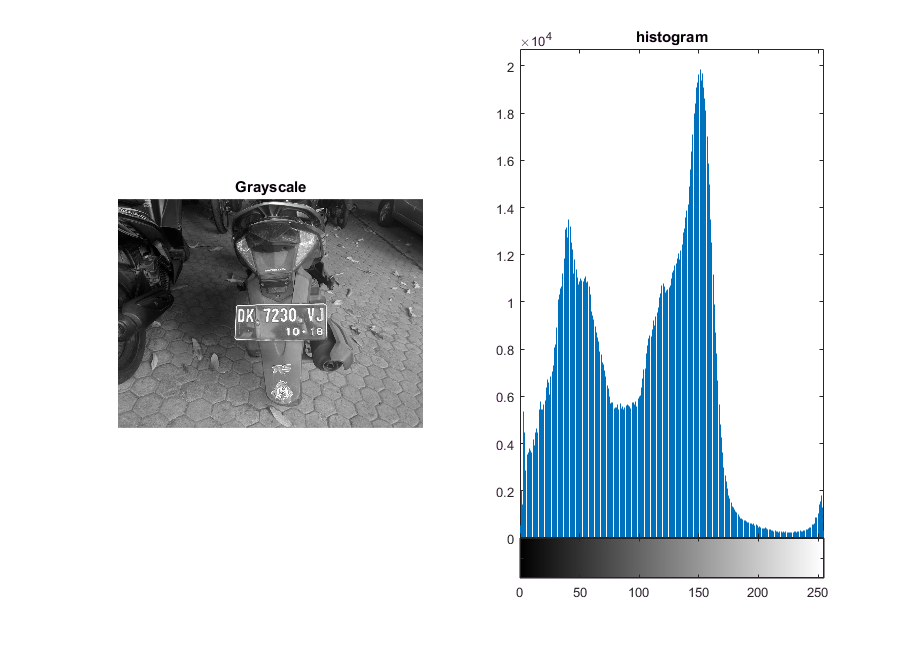

Im1 = rgb2gray(I); 
figure(2),
subplot(1,2,1),
imshow(Im1); 
title('Grayscale');

figure(2),
subplot(1,2,2),
imhist(Im1);
title('histogram');

Penambahan Contras

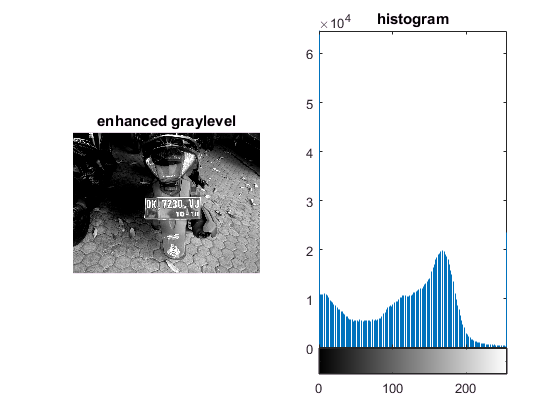

Im2 = imadjust(Im1,[0.2,0.8],[0,1]);
figure(3),
subplot(1,2,1),
imshow(Im2);
title('enhanced graylevel');

figure(3),
subplot(1,2,2),
imhist(Im2);
title('histogram');

Erosi

se = [1;1;1];
Im3 = imerode(Im2,se);
figure(5),
imshow(Im3);

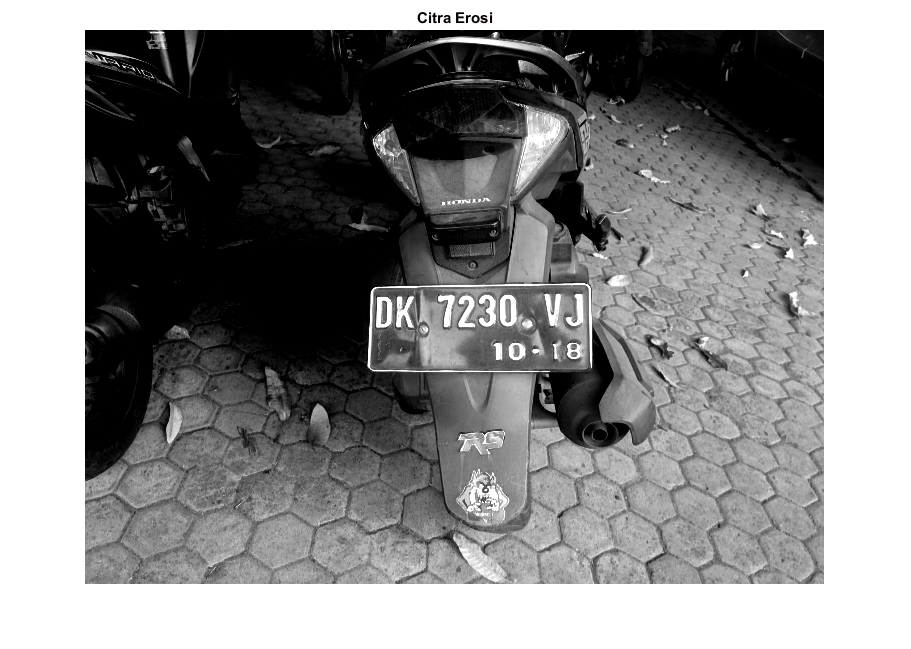

title('Citra Erosi');

Closing

se = strel('rectangle',[25,25]);
Im4 = imclose(Im3,se);
figure(6),
imshow(Im4);

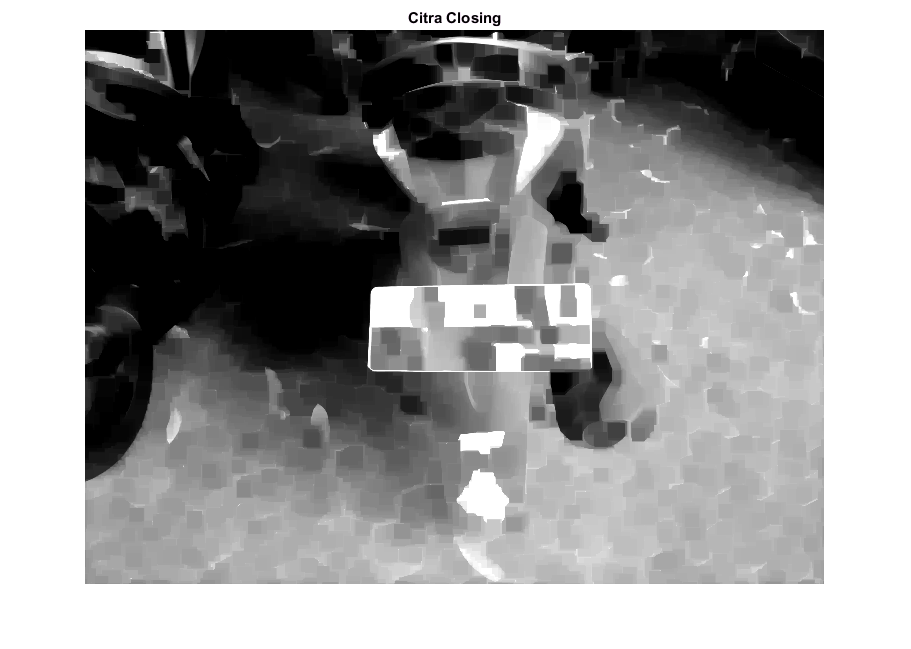

title('Citra Closing');

Pengurangan Noise

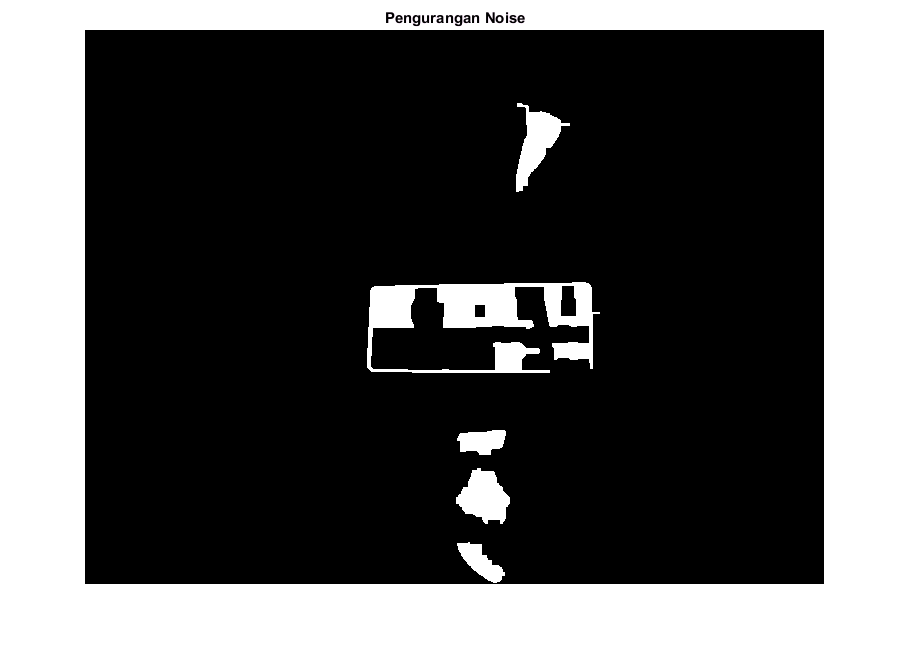

Im5 = double((Im4)>220);               
Im5 = bwareaopen(Im5,2000);
se = strel('rectangle',[5,5]);
Im5 = imdilate(Im5,se);
figure(7),
imshow(Im5);
title('Pengurangan Noise');

Cek Plat

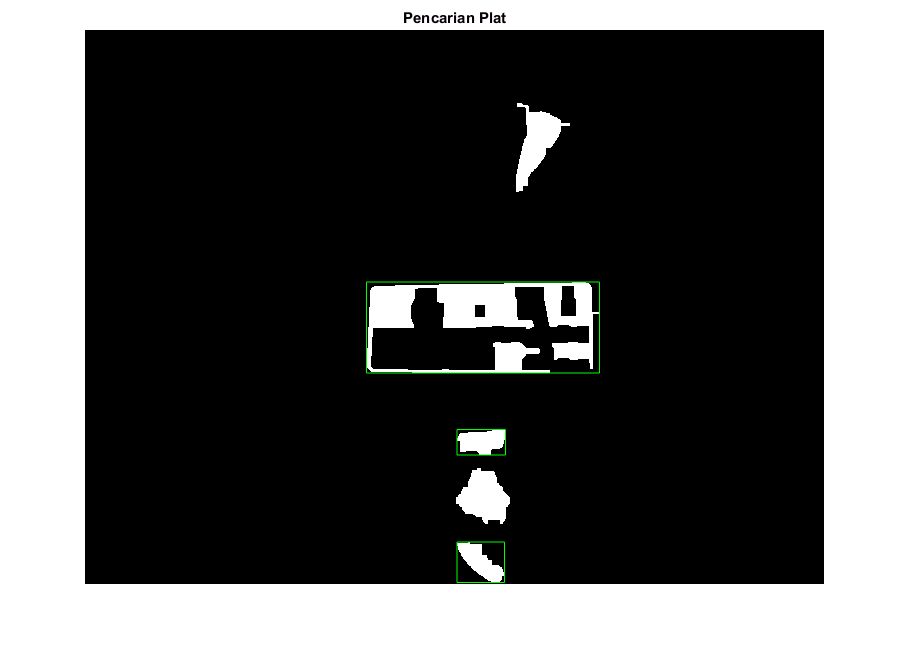

S = regionprops(Im5,'BoundingBox', 'ConvexArea', 'Eccentricity', 'Area');
[~,idx]=sort([S.Area]);
S=S(idx);

figure(7),
imshow(Im5);
title('Pencarian Plat');
 
hold on ; %tetap mengaktifan figur citra biner di atas
for i=1:size(S,1)
    if ((S(i).BoundingBox(3)>S(i).BoundingBox(4))&&(S(i).Eccentricity>=0.8700)&&(S(i).Eccentricity<=0.9550))
        rectangle('Position', S(i).BoundingBox,'edgecolor','green');
        Plat = S(i).BoundingBox;
    end
end

Croping Plat

siz=size(Im5);
Plat_x=[Plat(1)+5 Plat(1)+Plat(3)-5];
Plat_y=[Plat(2)+5 Plat(2)+Plat(4)-5];
if Plat_x(1)<1, Plat_x(1)=1; end
if Plat_y(1)<1, Plat_y(1)=1; end
if Plat_x(2)>siz(2), Plat_x(2)=siz(2); end
if Plat_y(2)>siz(1), Plat_y(2)=siz(1); end

im=Im1;
hasil=im(Plat_y(1):Plat_y(2),Plat_x(1):Plat_x(2));

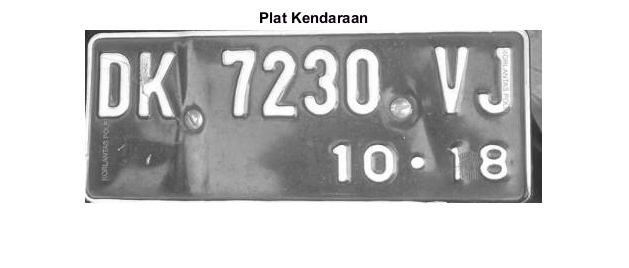


figure,
imshow(hasil);
title('Plat Kendaraan');

Resize dan Penambahan Kontras

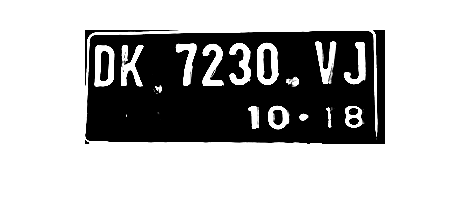

Im6 = imresize(hasil, [NaN 300]);
Im7 = imadjust(Im6,[0.7 0.8],[]);
figure,
imshow(Im7);

Remove Noise

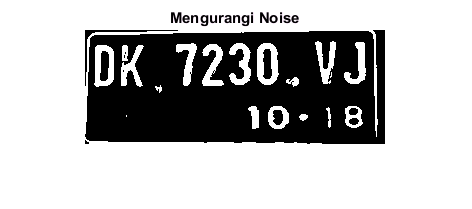

g_max = double(max(max(Im7)));
g_min = double(min(min(Im7)));
T = round(g_max-(g_max-g_min)/3);

Im8 = double((Im7)>=T);

figure,

imshow(Im8),
title('Mengurangi Noise');

Filtering dan Binarisasi

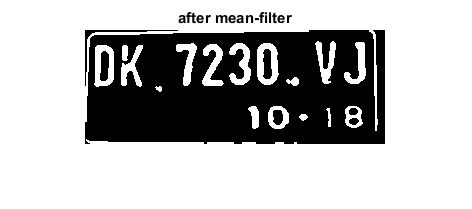

h = fspecial('average',3);
Im9 = imbinarize(round(filter2(h,double(Im8))));
figure,
imshow(Im9),
title('Filter Mean');

Menghilangkan Citra yang menyentuh border dan closing

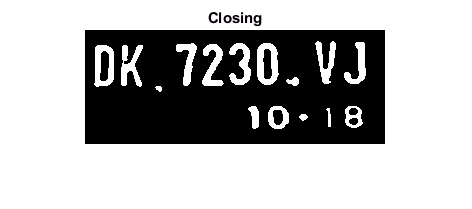

h = fspecial('average',3);
Im10 = imclearborder(Im9, 4);
Im11 = bwmorph(Im10,'close');
figure,
imshow(Im11),
title('Closing');

%se = strel('rectangle',[2,2]);
%erosi = imerode(d,se);
%figure,
%imshow(erosi),
%title('after mean-filter');

Mencari Karakter

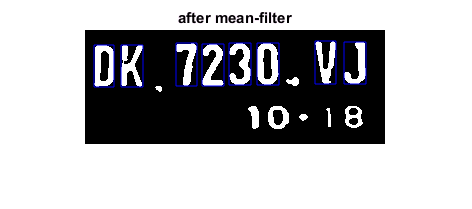

char = regionprops(Im11,'BoundingBox', 'Area', 'Eccentricity','Centroid');

figure;
imshow(Im11),
title('after mean-filter');
hold on ; %tetap mengaktifan figur citra biner di atas

for i=1:size(char,1)
    %tes(i) = char(i).Eccentricity;
    if (char(i).Area>=235)&&(char(i).Eccentricity>=0.800)&&(char(i).Eccentricity<=0.990)
    %cfix{i} = char(i).BoundingBox;
    rectangle('Position', char(i).BoundingBox,'edgecolor','blue');
    end
end

%rectangle('Position', char(33).BoundingBox,'edgecolor','red');

perlu clustering centroid dengan mencari centroid yg memiliki jarak sejajar

Pemotongan karakter dan menyimpannya

generationID = 2;
L=bwlabel(Im11,8);
siz=size(Im11);
n=max(L(:)); % number of objects
ObjCell=cell(n,1);
imageId = 1;
z = 1;
for i=1:n
      % Get the bb of the i-th object and offest by 2 pixels in all
      % directions
      char_i=ceil(char(i).BoundingBox);
      char_x=[char_i(1)-2 char_i(1)+char_i(3)+2];
      char_y=[char_i(2)-2 char_i(2)+char_i(4)+2];
      if char_x(1)<1, char_x(1)=1; end
      if char_y(1)<1, char_y(1)=1; end
      if char_x(2)>siz(2), char_x(2)=siz(2); end
      if char_y(2)>siz(1), char_y(2)=siz(1); end
      % Crop the object and write to ObjCell
      imchar=L==i;
      charfix{i}=imchar(char_y(1):char_y(2),char_x(1):char_x(2));
      
      if (char(i).Area<=2100)&&(char(i).Area>=235)&&(char(i).Eccentricity>=0.800)&&(char(i).Eccentricity<=0.990)
          img = imresize(charfix{i},[32, 16]);
          %img = bwmorph(img, 'thin', 'inf');
          imwrite(img, ['datauji/' num2str(generationID,'%d') '_' num2str(z,'%d') '.bmp'], 'bmp');
          imageId = imageId + 1;
          cf{i} = charfix{i};
          z = z +1;
      end
end

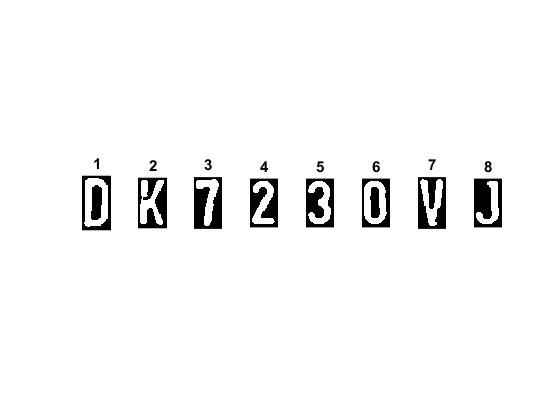

cf = cf(~cellfun(@isempty, cf));
p=length(cf);
figure
for j=1:p
    subplot(1,p,j)
    imshow(cf{j});
    title(sprintf('K %d', j));
end

Load Template

load templates
global templates;

Template Matching Per karakter

for flag2=1:p
    n2=imread(strcat('datauji\',num2str(generationID,'%d'),'_',num2str(flag2),'.bmp'));
    img_r=imresize(n2,[32 16]);
    letter=read_letter(img_r,36);
    result(flag2)=letter;
end

sem = 0.2809

sem = 0.6975

sem = 0.6123

sem = 0.9275

sem = 0.1847

sem = 0.2459

sem = 0.2587

sem = 0.0538

sem = -0.1310

sem = 0.4063

sem = 0.3353

sem = 0.1118

sem = -0.0053

sem = 0.0575

sem = 0.5795

sem = 0.5466

sem = 0.4729

sem = 0.5597

sem = 0.3071

sem = -0.1814

sem = 0.7185

sem = 0.2769

sem = 0.2981

sem = 0.1104

sem = -0.0196

sem = -0.0202

sem = 0.0607

sem = 0.2526

sem = 0.4821

sem = 0.1492

sem = 0.5305

sem = 0.6272

sem = 0.1775

sem = 0.4181

sem = 0.7104

sem = 0.6346

sem = 0.2044

sem = 0.2932

sem = 0.3681

sem = 0.2663

sem = 0.2169

sem = 0.2898

sem = 0.1030

sem = 0.1003

sem = -0.0496

sem = 0.0377

sem = 0.7289

sem = 0.1818

sem = 0.1386

sem = 0.2104

sem = 0.2633

sem = 0.3292

sem = 0.0689

sem = 0.4569

sem = 0.1699

sem = 0.0582

sem = 0.3763

sem = 0.1488

sem = 0.3696

sem = 0.4981

sem = 0.2325

sem = 0.1480

sem = 0.1455

sem = 0.2684

sem = 0.1420

sem = 0.3125

sem = 0.1750

sem = 0.3234

sem = 0.1132

sem = 0.1240

sem = 0.1299

sem = 0.2160

sem = 0.0129

sem = 0.2253

sem = 0.1387

sem = 0.0990

sem = -0.0248

sem = -0.0066

sem = -0.0389

sem = -0.3571

sem = 0.4079

sem = 0.1084

sem = 0.1586

sem = -0.2636

sem = -0.0230

sem = -0.3396

sem = 0.0980

sem = 0.2588

sem = -0.0575

sem = 0.1853

sem = 0.1247

sem = 0.5659

sem = 0.1123

sem = 0.2979

sem = 0.1522

sem = 0.2992

sem = 0.5360

sem = 0.3683

sem = 0.5947

sem = 0.4579

sem = 0.3340

sem = 0.0067

sem = 0.1338

sem = 0.1428

sem = 0.7844

sem = -0.0909

sem = 0.2367

sem = 0.0718

sem = 0.1402

sem = 0.4790

sem = 0.3584

sem = 0.3230

sem = 0.1370

sem = 0.0726

sem = 0.1037

sem = -0.2281

sem = 0.3071

sem = 0.2558

sem = 0.3198

sem = 0.0334

sem = -0.1805

sem = -0.2857

sem = 0.4179

sem = 0.5253

sem = 0.0885

sem = 0.4173

sem = 0.2347

sem = 0.2361

sem = 0.2117

sem = 0.1564

sem = 0.1705

sem = 0.3865

sem = 0.3301

sem = 0.5623

sem = 0.3646

sem = 0.8496

sem = 0.4877

sem = 0.1104

sem = 0.2149

sem = 0.3393

sem = 0.3911

sem = 0.1883

sem = 0.3898

sem = 0.2888

sem = 0.2369

sem = 0.6326

sem = 0.5084

sem = 0.5650

sem = 0.0554

sem = 0.0323

sem = 0.2329

sem = -0.1289

sem = 0.0435

sem = 0.5486

sem = 0.1971

sem = -0.0729

sem = -0.1087

sem = -0.1541

sem = 0.5229

sem = 0.4022

sem = 0.2829

sem = 0.4818

sem = 0.3153

sem = 0.0467

sem = 0.5559

sem = 0.1888

sem = 0.1958

sem = 0.1353

sem = 0.0996

sem = 0.1715

sem = 0.4242

sem = 0.4946

sem = 0.8349

sem = 0.0296

sem = 0.4877

sem = 0.5671

sem = 0.4421

sem = 0.3098

sem = 0.6588

sem = 0.5512

sem = 0.2767

sem = 0.6626

sem = 0.7079

sem = 0.6632

sem = 0.2354

sem = 0.2574

sem = 0.2664

sem = 0.0060

sem = -0.1211

sem = 0.3891

sem = 0.2831

sem = 0.1877

sem = -0.0433

sem = -0.0540

sem = 0.7107

sem = 0.4623

sem = 0.4507

sem = 0.5466

sem = 0.2390

sem = -0.1155

sem = 0.7206

sem = 0.2533

sem = 0.3262

sem = 0.0379

sem = -0.0130

sem = -0.0247

sem = 0.2309

sem = 0.3127

sem = 0.5598

sem = 0.1092

sem = 0.5116

sem = 0.7144

sem = 0.2720

sem = 0.3833

sem = 0.5763

sem = 0.7249

sem = 0.0389

sem = 0.3804

sem = 0.1916

sem = 0.4120

sem = -0.0627

sem = -0.0214

sem = -0.1661

sem = -0.1553

sem = 0.1204

sem = 0.1643

sem = 0.1773

sem = -0.1141

sem = 0.1802

sem = -0.1528

sem = 0.2117

sem = 0.3931

sem = 0.0450

sem = 0.2879

sem = 0.0464

sem = 0.0989

sem = 0.4502

sem = 0.6764

sem = 0.3854

sem = 0.3542

sem = 0.5452

sem = 0.0540

sem = 0.2415

sem = 0.2216

sem = 0.2340

sem = 0.0297

sem = 0.2340

sem = 0.2332

sem = 0.4942

sem = -0.0356

sem = 0.4082

sem = 0.1197

sem = 0.1754

sem = 0.4360

sem = 0.2672

sem = 0.4934

sem = -0.0379

sem = -0.0759

sem = 0.1285

sem = -0.1121

sem = -0.0852

sem = 0.8136

sem = 0.1278

sem = -0.1917

sem = -0.0761

sem = -0.1463

sem = 0.3777

sem = 0.1592

sem = 0.2500

sem = 0.2527

sem = 0.1587

sem = -0.0216

sem = 0.6135

sem = 0.2013

sem = 0.1945

sem = 0.0984

sem = 0.0158

sem = 0.1466

sem = 0.2646

sem = 0.2711

sem = 0.6332

sem = 0.1316

sem = 0.4548

sem = 0.3277

sem = 0.3628

sem = 0.2209

sem = 0.5041

sem = 0.4735

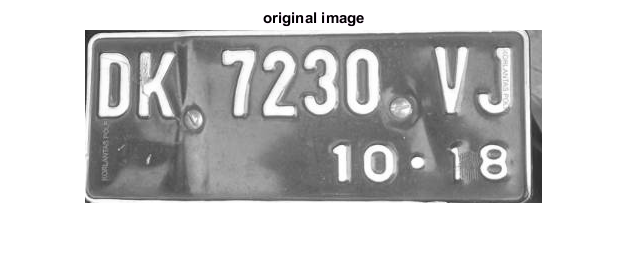

figure(11)
imshow(hasil);
title('original image');

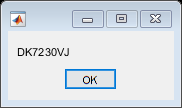

msgbox(result)